# Matpower Simulation

Matpower is an open source simulation engine and optimal power flow calculator for MATLAB. More info here: [https://matpower.org/.](https://matpower.org/.)

We want to use it to simulate the behaviour of our identification algorithm on real networks.

## Network definition

We choose a 33 bus feeder - source here: [https://egriddata.org/dataset/33-bus-radial-distribution-system](https://egriddata.org/dataset/33-bus-radial-distribution-system) 

clear all
close all
clc
rng(42);

We load the data.

define_constants;
mpc = loadcase('case33bw');

We define useful constants and we derive the impedence matrix.

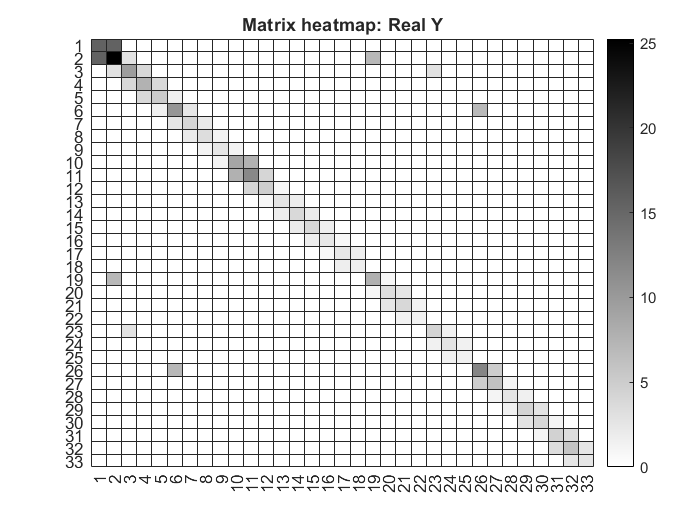

Y = full(makeYbus(mpc));
load_mask = mpc.bus(:, BUS_TYPE) == PQ;
n = size(mpc.bus, 1);
n_gen = size(mpc.gen, 1);
n_load = n - n_gen;
matrix_heatmap(Y, 'Real Y');

We check that the admittance matrix is in fact Laplacian.

max(sum(Y, 2))

ans = -8.8818e-16 + 8.8818e-16i

issymmetric(Y)

ans = logical
   1


Looks like it is, in fact!

## Grid simulation

We choose an arbitrary number of time steps and we simulate the evolution of the grid over those instants. 

At the moment, active and reactive power requirements for loads are random, but we will shortly move towards real profiles. [TODO]

samples = 200;
load_avg_pd = mpc.bus(load_mask, PD);
load_avg_qd = mpc.bus(load_mask, QD);
for i = 1:samples
    mpc.bus(load_mask, PD) = normrnd(load_avg_pd, 0.05 * load_avg_pd);
    mpc.bus(load_mask, QD) = normrnd(load_avg_qd, 0.05 * load_avg_qd);
    res = runpf(mpc);
    bus_phase = res.bus(:, VA) * pi / 180;
    bus_magnitude = res.bus(:, VM);
    bus_voltage(:, i) = bus_magnitude .* (cos(bus_phase) + sqrt(-1) * sin(bus_phase));
    load_pd(:, i) = res.bus(load_mask, PD);
    load_qd(:, i) = res.bus(load_mask, QD);
end


MATPOWER Version 7.0, 20-Jun-2019 -- AC Power Flow (Newton)

Newton's method power flow (power balance, polar) converged in 3 iterations.

Converged in 0.06 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses             33     Total Gen Capacity      10.0         -10.0 to 10.0
Generators         1     On-line Capacity        10.0         -10.0 to 10.0
Committed Gens     1     Generation (actual)      3.9               2.4
Loads             32     Load                     3.7               2.3
  Fixed           32       Fixed                  3.7               2.3
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -

bus_current = Y * bus_voltage;

We visualize the evolution of the voltage and the current for a random node.

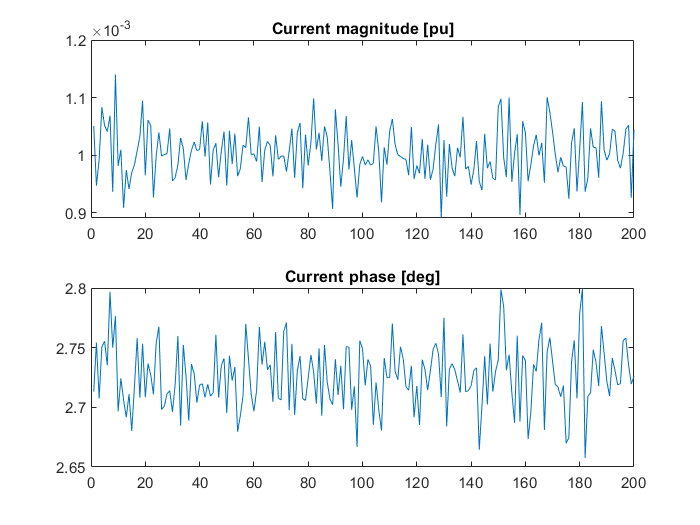

viz_node = 3;
viz_current = bus_current(viz_node, :);
viz_voltage = bus_voltage(viz_node, :);

figure()
subplot(2, 1, 1);
plot(1:samples, abs(viz_current));
title('Current magnitude [pu]');
subplot(2, 1, 2);
plot(1:samples, angle(viz_current));
title('Current phase [deg]');

figure()
subplot(2, 1, 1);
plot(1:samples, abs(viz_voltage));
title('Voltage magnitude [pu]');
subplot(2, 1, 2);
plot(1:samples, angle(viz_voltage));

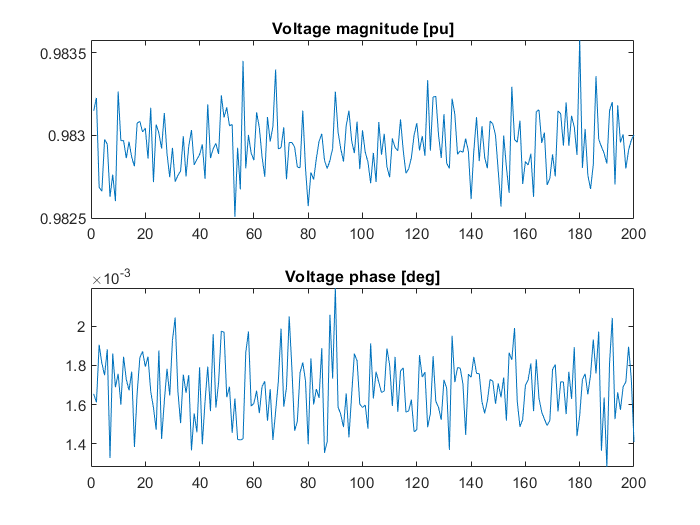

title('Voltage phase [deg]');

## Error metrics

We define the error metrics we are going to use to test the accuracy of the estimation algorithms. Define the error matrix $Y_e = \left |Y - \hat Y \right|$. We are going to use the following error metrics:

- Frobenius norm of $Y_e$

- Max norm of $Y_e$

Moreover, we will resort to an heatmap to see how the absoulte error in the estimation of the admittance matrix is distributed among the different elements.

## OLS estimation

As a first benchmark, we estimate the admittance matrix using Ordinary Least.

Froebius norm for OLS is 1.174e-09
Max norm for OLS is 2.9983e-10


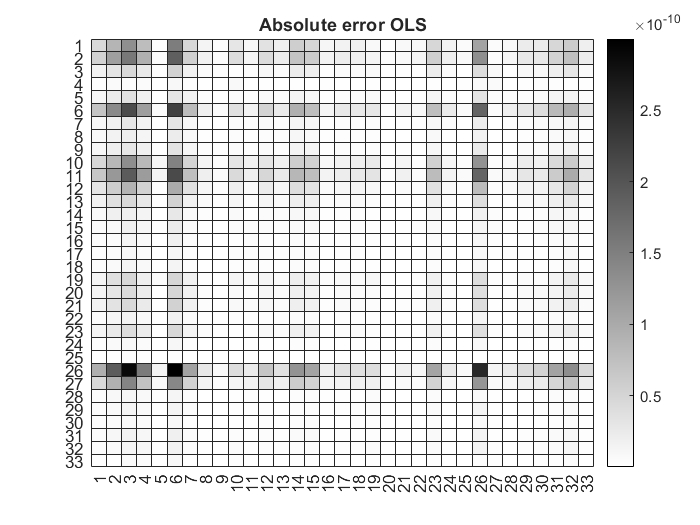

Y_hat_ols = conj(bus_voltage' \ bus_current');
error_metrics(Y, Y_hat_ols, 'OLS');

## Lasso Estimation

Following Ardakanian et al, we now resort to Lasso in order to peform the same estimation.

idx = 1:n;
nidx = setdiff(1:n,idx);
[Y22_est, Y12_est, Y11_est] = postprocessing(bus_voltage,bus_current,idx,nidx,Y);

Lasso method is being used...


best lambda is 0.0001
maximum absolute error is 7.0774e-05
error norm is 0.0006969
no. nonzero elements: 97
Thresholded lasso method with refitting is being used...
best lambda is 0.0001
maximum absolute error is 2.5208e-10
error norm is 5.383e-10
no. nonzero elements: 97
Adaptive lasso method with OLS based weights is being used...
optimal gamma is 0.5
best lambda is 0.0001
maximum absolute error is 9.7388e-05
error norm is 0.00056637
no. nonzero elements: 97
Thresholded lasso with refitting outperformed other methods
Relative error (pct): 5.4789e-09


Froebius norm for Lasso is 5.383e-10
Max norm for Lasso is 2.5208e-10


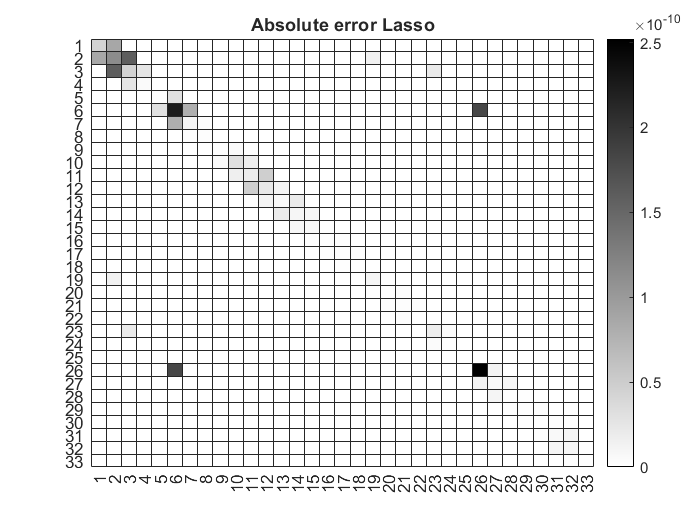

Y_hat_lasso  = [Y11_est Y12_est; Y12_est.' Y22_est];
error_metrics(Y, Y_hat_lasso, 'Lasso');